# CODIGO PROYECTO LAB MODELACIÓN 2.

## Limpiar el espacio de trabajo y la ventana de comandos

% Limpia el espacio de trabajo y la ventana de comandos
% Inicia el cronómetro para medir el tiempo de ejecución

close all
clear all
clc

tic % empezamos a tomar el tiempo

## Primeros pasos (datos experimentales, parametros, condiciones iniciales, etc).

%% Datos experimentales [añadir ref]

tex= [0 5 10 15 20 25 30 35 40 45]; %tiempo 
p53ex= [8.293 8.102333333 7.561 7.208666667 7.382333333 7.640666667 7.760666667 7.893333333 8.142 8.301333333];
Stat3ex= [10.32066667 10.96533333 11.15966667 11.16066667 11.167 11.006 10.75666667 10.59766667 10.35066667 10.505];
Np63ex= [7.721333333 7.14 6.675 6.946333333 7.060333333 6.731666667 6.723666667 6.757 6.810666667 6.883333333];

%% PARÁMETROS - PRIMER ESTIMADO
% Parámetros para las ecuaciones diferenciales del modelo

% --- p53 ---
% dp53 = (Pp53 + B*(p53^N)/(k^N+p53^N) + ANp63p53*Np63)*C1*(1/(1+dNp63p53*Np63))-p53*Dp53;
Pp53 = 1; % Producción basal de p53 
N = 1; % Exponente de Hill
k = 1; % Constante de saturacion
B = 1; % Coeficiente retroalimentacion positiva
ANp63p53 = 1; % Efecto de Np63 sobre p53 sobre transcripcion positiva
C1 = 1; % Coeficiente transcripcion negativa
dNp63p53 = 1; % Efecto de np63 sobre p53 - transcripcion negativa
Dp53 = 1; % Degradacion basal de p53

% --- Stat3 ---
% dStat3 = (Pstat3 + ANp63s*Np63 + Ap53s*p53) - Dstat3*Stat3;
Pstat3 = 1; % Produccion basal de stat3
ANp63s = 1; % Efecto de Np63 sobre stat3 - transcripcion
Ap53s = 1; % Efecto de p53 sobre stat3 - transcripcion
Dstat3 = 1; % degradacion basal de stat3

% --- Np63 ---
% dNp63 = (PNp63 + Astat3Np*Stat3)*C2*(1/(1+dp53NP*p53))*C3*(1/(1+dNp63Np63*Np63)) - DNp63*Np63;
PNp63 = 10; % Produccion basal de p63
Astat3Np = 1; % Efecto de Stat3 sobre Np63 - transcripacion
C2 = 1; % Coeficiente transcripcion negativa
dp53NP = 1; % Efecto de p53 sobre Np63 - transcripcion negativa
C3 = 1; % Coeficiente transcripcion negativa
dNp63Np63 = 1; % Efecto de Np63 sobre si misma - transcripcion negativa
DNp63 = 5; % Degradacion basal de p63 


% Condiciones iniciales y tiempo de simulación
tspan = [0 50]; 
y0 = [p53ex(1) Stat3ex(1) Np63ex(1)]; 


% Vector de parámetros iniciales
x0 = [Pp53, N, k, B, ANp63p53, C1, dNp63p53, Dp53, ...
    Pstat3, ANp63s, Ap53s, Dstat3, ...
    PNp63, Astat3Np, C2, dp53NP, C3, dNp63Np63, DNp63];

## SIMULACIONES

ans =     1.3441    3.0103    0.6662
    0.5300   -0.2070   -1.7370
  -14.9342  -15.0014   -1.0673
   -0.9400    7.1314    7.0714


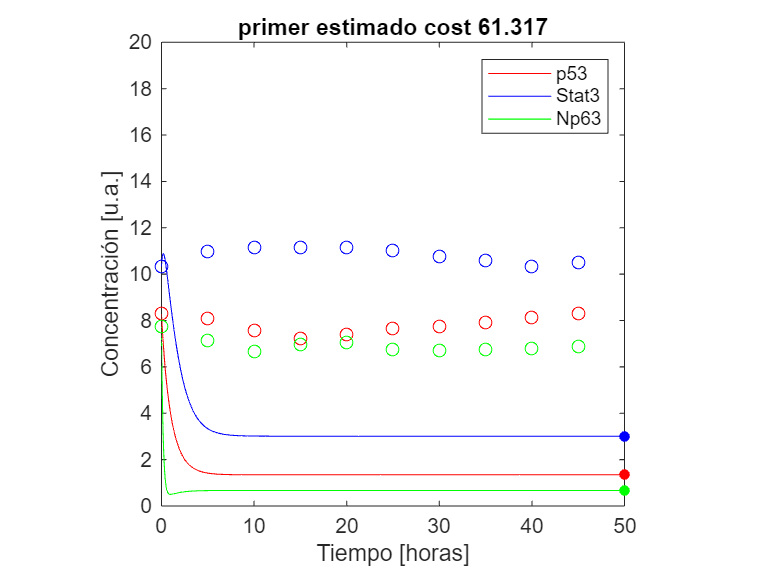

Plot_with_data('primer estimado', x0,tex,p53ex,Stat3ex,Np63ex,y0, tspan)

## 1.-  Empezamos con una Optimizacion Local

% Configurar opciones de optimización
options= optimset('Algorithm','active-set','TolFun',1e-6, ...
    'TolX',1e-6,'MaxIter',1e6,'MaxFunEvals',1e8);

% Ejecutar optimización local
[xLocal,J,flag]=fminsearch(@(x)CostFunction_keratinocytes(x,tex,p53ex,Stat3ex,Np63ex,y0, tspan),x0,options);

% Mostrar resultados
fprintf('Resultado de la optimización local (xLocal):\n');

Resultado de la optimización local (xLocal):


disp(xLocal);

    1.1380    0.6184    1.8558    1.6019    1.3864    0.8905    1.0944    0.1597    0.9819    0.0053    1.1090    0.8895    5.7201    0.9350    1.2659    0.0000    2.8150    0.2113    3.3663




% Nota: Esta optimización puede contener valores negativos
fprintf('Advertencia: la solución contiene posibles valores negativos.\n');

Advertencia: la solución contiene posibles valores negativos.


ans =     7.7253   10.7765    6.8394


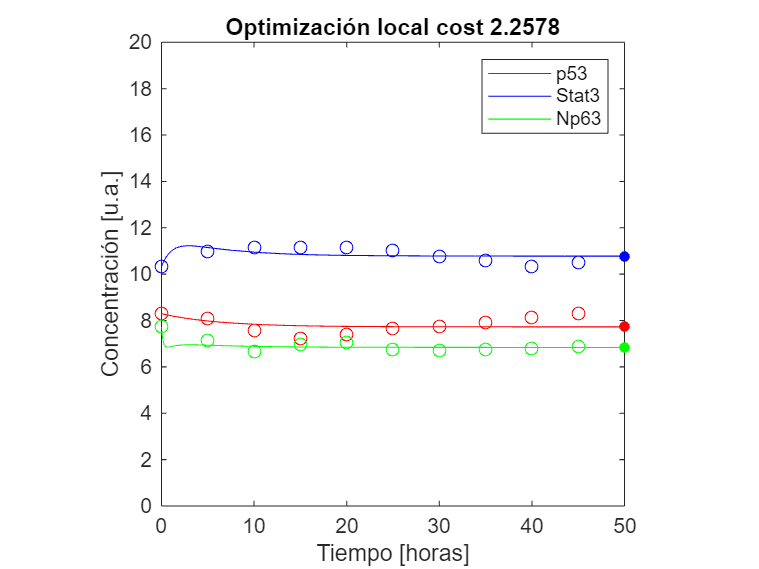


% Graficar resultados
Plot_with_data('Optimización local', xLocal, tex, p53ex, Stat3ex, Np63ex, y0, tspan);

## 2.- Optimización Global: Multi-start

% Definir el rango de búsqueda de los parámetros
% Si no se tiene un valor inicial razonable, se busca en un hipercubo entre 0 y 1000
% El número de dimensiones corresponde al número de parámetros en x0
lb = 0 * ones(size(x0));        % Límite inferior de búsqueda
ub = 1000 * ones(size(lb));     % Límite superior de búsqueda
 
% % Límite de tiempo para la optimización (en segundos)
tStop = 36000;  % 10 horas
 
% % Definir la función objetivo: función de costo a minimizar
% % Esta función compara el modelo con los datos experimentales
min = @(x) CostFunction_keratinocytes(x, tex, p53ex, Stat3ex,Np63ex, y0, tspan);
 
% % Configurar el algoritmo MultiStart para encontrar el mínimo global
ms = MultiStart('StartPointsToRun', 'bounds-ineqs', 'Display', 'iter');
 
% Crear el problema de optimización con fmincon
problem = createOptimProblem('fmincon', ...
    'x0', xLocal, ...
    'objective', min, ...
    'lb', lb, ...
    'ub', ub);

% Ejecutar MultiStart con 150 puntos iniciales aleatorios
[xMS, CostMS] = run(ms, problem, 150);

    Run       Local       Local      Local    Local   First-order
   Index     exitflag      f(x)     # iter   F-count   optimality
       1         2        2.258         2        84       0.05402
       2         0         2.37       148      3016       0.01119


       3         1        1e+12         0        20             0
       4         1         2.37        95      1959     5.882e-07


       5         1        1e+12         0        20             0


       6         1        1e+12         0        20             0


       7         1        1e+12         0        20             0


       8         1        1e+12         0        20             0


       9         1        1e+12         0        20             0


      10         1        1e+12         0        20             0


      11         1        1e+12         0        20             0
      12         1         2.37        48      1008     4.239e-07


      13         1        1e+12         0        20             0


      14         1        1e+12         0        20             0


      15         1         2.37        77      1590     6.056e-07


      16         1        1e+12         0        20             0
      17         1         2.37        66      1352     2.508e-07


      18         1         2.37        44       920     5.057e-08


      19         1        1e+12         0        20             0


      20         1        1e+12         0        20             0


      21         1        1e+12         0        20             0
      22         1         2.37        37       771     5.167e-08


      23         0         2.37       148      3017      0.001751


      24         1        1e+12         0        20             0


      25         1        1e+12         0        20             0
      26         1         2.37       136      2786     4.162e-07
      27         1         2.37        42       871     6.114e-08


      28         0         2.37       147      3007       0.07503


      29         1        1e+12         0        20             0


      30         1        1e+12         0        20             0


      31         1        1e+12         0        20             0


      32         1        1e+12         0        20             0


      33         1        1e+12         0        20             0


      34         0         2.37       142      3006      1.05e-05


      35         1        1e+12         0        20             0


      36         1         2.37        39       815     1.056e-07


      37         1        1e+12         0        20             0


      38         1        1e+12         0        20             0


      39         1        1e+12         0        20             0


      40         1        1e+12         0        20             0


      41         1        1e+12         0        20             0
      42         1         2.37       120      2456     3.287e-07


      43         1        1e+12         0        20             0


      44         1        1e+12         0        20             0


      45         1        1e+12         0        20             0


      46         1        1e+12         0        20             0


      47         1        1e+12         0        20             0
      48         1         2.37       126      2571     1.738e-07


      49         1        1e+12         0        20             0


      50         1        1e+12         0        20             0


      51         1        1e+12         0        20             0


      52         1        1e+12         0        20             0


      53         1        1e+12         0        20             0


      54         1        1e+12         0        20             0


      55         1        1e+12         0        20             0


      56         1        1e+12         0        20             0


      57         1        1e+12         0        20             0


      58         1        1e+12         0        20             0


      59         1        1e+12         0        20             0


      60         1        1e+12         0        20             0


      61         1        1e+12         0        20             0


      62         1        1e+12         0        20             0


      63         1         2.37        54      1114     2.892e-07


      64         2         2.37       119      2473         4.312


      65         1        1e+12         0        20             0


      66         1         2.37        48       999     4.279e-07


      67         1        1e+12         0        20             0


      68         0         2.37       146      3002     1.487e-06


      69         1         2.37        28       590     4.356e-07
      70         1         2.37        93      1940     9.423e-07
      71         0         2.37       147      3001     0.0001104


      72         1        1e+12         0        20             0


      73         0         2.37       148      3019     0.0005899


      74         1        1e+12         0        20             0


      75         1        1e+12         0        20             0
      76         1         2.37        50      1031     7.896e-08


      77         1        1e+12         0        20             0


      78         1        1e+12         0        20             0


      79         1        1e+12         0        20             0


      80         1         2.37        44       917     1.952e-07


      81         1         2.37        53      1116     6.131e-07


      82         1        1e+12         0        20             0


      83         1        1e+12         0        20             0


      84         1         2.37        92      1890     1.362e-07


      85         1        1e+12         0        20             0


      86         1        1e+12         0        20             0


      87         1         2.37        74      1523     4.123e-07
      88         0        2.795       146      3003         3.787


      89         1        1e+12         0        20             0


      90         1        1e+12         0        20             0


      91         1        1e+12         0        20             0


      92         1        1e+12         0        20             0
      93         1         2.37        54      1127     5.878e-08
      94         1         2.37       108      2213     7.333e-07


      95         1        1e+12         0        20             0
      96         1         2.37        40       845     9.049e-08


      97         1        1e+12         0        20             0


      98         1        1e+12         0        20             0


      99         1        1e+12         0        20             0


     100         1        1e+12         0        20             0


     101         0        15.65       147      3004       0.04261


     102         1        1e+12         0        20             0


     103         1        1e+12         0        20             0


     104         1        1e+12         0        20             0


     105         1        1e+12         0        20             0


     106         1        1e+12         0        20             0


     107         1        1e+12         0        20             0


     108         1        1e+12         0        20             0


     109         1        1e+12         0        20             0


     110         1        1e+12         0        20             0


     111         1        1e+12         0        20             0


     112         1        1e+12         0        20             0
     113         1         2.37        54      1113     2.318e-07


     114         1        1e+12         0        20             0


     115         1        1e+12         0        20             0


     116         1        1e+12         0        20             0
     117         1         2.37        33       684     1.393e-07


     118         1         2.37       103      2146     7.215e-08


     119         1        1e+12         0        20             0


     120         1        1e+12         0        20             0
     121         1         2.37        90      1851      2.54e-07


     122         1        1e+12         0        20             0
     123         1         2.37       141      2900     1.821e-07


     124         1        1e+12         0        20             0


     125         1        1e+12         0        20             0


     126         1        1e+12         0        20             0


     127         1        1e+12         0        20             0


     128         1        1e+12         0        20             0


     129         1        1e+12         0        20             0


     130         1        1e+12         0        20             0


     131         1        1e+12         0        20             0
     132         0         2.37       146      3005     3.015e-05
     133         1         2.37        45       935      1.01e-07


 
%% Mostrar resultados de forma clara

fprintf('\n===== Resultados de la Optimización Global (Multi-start) =====\n');
fprintf('Parámetros óptimos encontrados:\n');
disp(xMS)

fprintf('Costo asociado a la solución óptima: %.6f\n', CostMS);
fprintf('==============================================================\n\n');

%% Simulación del modelo con los parámetros óptimos encontrados

% Graficar los resultados del modelo optimizado junto con los datos experimentales
Plot_with_data('Optimización global multi-start', xMS, tex, p53ex, Stat3ex,Np63ex,y0, tspan);

## 3.- Optimización Global: levenberg-marquardt

Objective_Function=@(x)CostFunction_keratinocytes(x,tex,p53ex,Stat3ex,Np63ex, y0, tspan)
% the next arguments are empty, but we need to put placehoders nonetheless
A = [];
b = [];
Aeq = [];
beq = [];

% Run the optimization!

options = optimoptions(@lsqnonlin,'OptimalityTolerance',1e-8, 'Algorithm','levenberg-marquardt', 'UseParallel', true, 'FunctionTolerance', 1e-8,  'MaxIterations', 5000,'MaxFunctionEvaluations',10000)

% Run the optimization!

xLM = lsqnonlin(Objective_Function,xMS,lb,ub,options)
xLM
CostLM=Objective_Function(xLM)

Plot_with_data('levenberg-marquardt', xLM,tex,p53ex,Stat3ex,Np63ex, y0, tspan)


## 4.- Optimización Global: Global search

gs=GlobalSearch('StartPointsToRun','bounds-ineqs','Display','iter');
problem_GS=createOptimProblem('fmincon','x0',xLM,'objective',min,'lb',lb,'ub',ub);
[xGS,CostGS]=run(gs,problem_GS);
        
toc

Plot_with_data('GlobalSearch', xGS,tex,p53ex,Stat3ex,Np63ex, y0, tspan)


%% guarda el vector de parámetros

save("Optimal_parameters.mat","xGS","xMS")

## Funciones a utilizar:

function Cost = CostFunction_keratinocytes(x,tex,p53ex,Stat3ex,Np63ex,y0, tspan)
    % FUNCION DE COSTO: Dado un vector de parámetros x, calcula la diferencia
    % entre el modelo simulado y los datos experimentales.

    % Si los parámetros no tienen sentido físico, penaliza con costo alto
    if any(x < 0) || any(isnan(x)) || any(isinf(x)) || any(x > 1e4)
        Cost = 1e12;
        return;
    end

    % Extraer parámetros (en el orden correcto)
    Pp53 = x(1); N = x(2); k = x(3); B = x(4); ANp63p53 = x(5); C1 = x(6);
    dNp63p53 = x(7); Dp53 = x(8); Pstat3 = x(9); ANp63s = x(10); Ap53s = x(11);
    Dstat3 = x(12); PNp63 = x(13); Astat3Np = x(14); C2 = x(15); dp53NP = x(16);
    C3 = x(17); dNp63Np63 = x(18); DNp63 = x(19);

    try
        % Configurar opciones del integrador (más estricto)
        options = odeset('RelTol',1e-6, 'AbsTol',1e-8, 'MaxStep',1);

        % Integrar el sistema
        Sol = ode15s(@(t, y) difer(t, y, B, Pp53, Pstat3, PNp63, N, k, ...
            ANp63p53, C1, dNp63p53, Dp53, ANp63s, Ap53s, Dstat3, ...
            Astat3Np, C2, dp53NP, C3, dNp63Np63, DNp63), ...
            tspan, y0, options);

        % Validar que la integración cubrió todos los puntos experimentales
        if max(Sol.x) < max(tex)
            Cost = 1e12; % Penalización si no se completó la integración
            return;
        end

        % Extraer resultados del modelo
        t1 = Sol.x;
        p53 = Sol.y(1,:);
        Stat3 = Sol.y(2,:);
        Np63 = Sol.y(3,:);

        % Interpolación en los tiempos de medición
        p53_interp = interp1(t1, p53, tex, 'linear', NaN);
        Stat3_interp = interp1(t1, Stat3, tex, 'linear', NaN);
        Np63_interp = interp1(t1, Np63, tex, 'linear', NaN);

        % Penalizar si hay NaN en la interpolación (fuera del rango)
        if any(isnan([p53_interp, Stat3_interp, Np63_interp]))
            Cost = 1e12;
            return;
        end

        % Calcular el costo como suma de errores cuadráticos
        Cost_p53 = sqrt(sum((p53_interp - p53ex).^2));
        Cost_Stat3 = sqrt(sum((Stat3_interp - Stat3ex).^2));
        Cost_Np63 = sqrt(sum((Np63_interp - Np63ex).^2));

        % Costo total (puedes ponderarlo si hay diferentes importancias)
        Cost = Cost_p53 + Cost_Stat3 + Cost_Np63;

    catch
        % Si ocurre cualquier error durante la integración, penalizar
        Cost = 1e12;
    end
end

         
function dx = difer(t, y, B, Pp53, Pstat3, PNp63, N, k, ANp63p53, C1, dNp63p53, Dp53, ANp63s, Ap53s, Dstat3, Astat3Np, C2, dp53NP, C3, dNp63Np63, DNp63)
    % Variables del sistema
    p53 = y(1); 
    Stat3 = y(2); 
    Np63 = y(3); 
    
    % Protección contra valores negativos o NaN
    if any(isnan(y)) || any(isinf(y)) || any(y < 0)
        dx = NaN * ones(size(y));  % penaliza en el integrador
        return;
    end

    % Evitar divisiones por cero y controlar exponenciales
    eps_val = 1e-6;  % pequeño valor de seguridad

    % Evitar valores negativos en potencias y divisores
    p53_safe = max(p53, eps_val);
    Np63_safe = max(Np63, eps_val);
    Stat3_safe = max(Stat3, eps_val);
    k_safe = max(k, eps_val);

    % Cálculo de derivadas con variables protegidas
    dp53 = (Pp53 + B * (p53_safe^N) / (k_safe^N + p53_safe^N) + ANp63p53 * Np63_safe) ...
            * C1 * (1 / (1 + dNp63p53 * Np63_safe)) - Dp53 * p53_safe;

    dStat3 = (Pstat3 + ANp63s * Np63_safe + Ap53s * p53_safe) - Dstat3 * Stat3_safe;

    dNp63 = (PNp63 + Astat3Np * Stat3_safe) ...
            * C2 * (1 / (1 + dp53NP * p53_safe)) ...
            * C3 * (1 / (1 + dNp63Np63 * Np63_safe)) - DNp63 * Np63_safe;

    dx = [dp53; dStat3; dNp63];
end

%% Función para graficar
function  Plot_with_data(label, x,tex,p53ex,Stat3ex,Np63ex,y0, tspan)

    Cost = CostFunction_keratinocytes(x,tex,p53ex,Stat3ex,Np63ex,y0, tspan);
    
    % Extraccion de parametros
    Pp53 = x(1); N = x(2); k = x(3); B = x(4); ANp63p53 = x(5); C1 = x(6); dNp63p53 = x(7); Dp53 = x(8);
    Pstat3 = x(9); ANp63s = x(10); Ap53s = x(11); Dstat3 = x(12);
    PNp63 = x(13); Astat3Np = x(14); C2 = x(15); dp53NP = x(16); C3 = x(17); dNp63Np63 = x(18); DNp63= x(19);

    [ts,y] = ode15s(@(t, y) difer(t, y, B, Pp53, Pstat3, PNp63, N, k, ANp63p53, C1, dNp63p53, Dp53, ANp63s, Ap53s, Dstat3, Astat3Np, C2, dp53NP, C3, dNp63Np63, DNp63), tspan, y0);
    
    figure;
    % Trayectorias dinamicas 
    l1=plot(ts, y(:,1), 'r', 'DisplayName', 'p53');
    hold on
    l2=plot(ts, y(:,2), 'b', 'DisplayName', 'Stat3');
    l3=plot(ts, y(:,3), 'g', 'DisplayName', 'Np63');
    xlabel('Tiempo [horas]')
    ylabel('Concentración [u.a.]')
    xlim([0, 50])
    scatter(tex, p53ex, 'r', 'DisplayName', 'p53 experimental')
    scatter(tex, Stat3ex, 'b', 'DisplayName', 'Stat3 experimental')
    scatter(tex, Np63ex, 'g', 'DisplayName', 'Np63 experimental')
    if (sum((x)<0)>0) % there are negative values
        title(['!! x has NEGATIVE VALUES ' label  'Cost=' num2str(Cost) ])%; 'x=' num2str(x) ])
    else
        title([label ' cost ' num2str(Cost) ])%; 'x=' num2str(x) ])
    end
    legend off
    % puntos de equilibrio
    Equilibrios_modelo_shamari(x)
    
    ySS=Equilibrios_modelo_shamari(x);
    
    
    for jj=1:1: length(ySS(:,1))
        % select only positive
        if sum((ySS(jj,:)<0))==0
            scatter(ts(end), ySS(jj,1), 25, 'r', 'filled')
            scatter(ts(end), ySS(jj,2), 25, 'b', 'filled')
            scatter(ts(end), ySS(jj,3), 25, 'g', 'filled')
        end
    end
    ylim([0, 20])
    axis square
    hold off
    
    legend([l1, l2 l3], 'p53', 'Stat3','Np63');

end

function Steady_states=Equilibrios_modelo_shamari(x)
    % Extraccion de parametros
    Pp53 = x(1); N = x(2); k = x(3); B = x(4); ANp63p53 = x(5); C1 = x(6); dNp63p53 = x(7); Dp53 = x(8);
    Pstat3 = x(9); ANp63s = x(10); Ap53s = x(11); Dstat3 = x(12);
    PNp63 = x(13); Astat3Np = x(14); C2 = x(15); dp53NP = x(16); C3 = x(17); dNp63Np63 = x(18); DNp63= x(19);
    
    % análisis de equilibios
    syms p53 Stat3 Np63 

    dp53      =0== ( Pp53 + B*(p53^N)/(k^N+p53^N) + ANp63p53*Np63)*C1*(1/(1+dNp63p53*Np63))-p53*Dp53;
    
    dStat3    =0== (Pstat3 + ANp63s*Np63 + Ap53s*p53) - Dstat3*Stat3;
   
    dNp63     =0== (PNp63 + Astat3Np*Stat3)*C2*(1/(1+dp53NP*p53))*C3*(1/(1+dNp63Np63*Np63)) - DNp63*Np63;
    
    equations = [dp53 dStat3 dNp63];
    vars       =[p53  Stat3   Np63];
    
    range = [NaN NaN; NaN NaN;NaN NaN];
    sol = vpasolve(equations, vars, range);
    
    Steady_states=double([sol.p53 sol.Stat3 sol.Np63]);
end